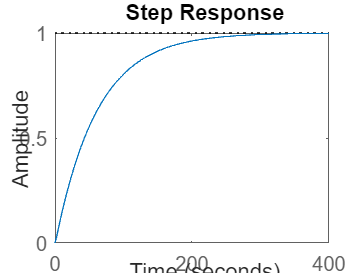

% LQR con efecto integrativo y cálculo de Q, R, N basado en Qy y Ru
clc; clear all; close all;

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;

A = [-b/J K/J; -K/L -R/L];
B = [0; 1/L];
C = [1 0];
D = 0;

nx = 2; % # de estados X
ny = 1; % # de salidas y
nu = 1; % # de entradas u


Qy = 1000000; 
Ru = 0.001; 

Q = C' * Qy * C;
R = D' * Qy * D + Ru;
N = C' * Qy * D;

% Aumentar el sistema para efecto integrativo
AOL = [A zeros(nx,ny); -C zeros(ny,ny)];
BOL = [B; zeros(ny,nu)];
QOL = blkdiag(Q, Qy); 

NOL = [N; zeros(ny, nu)]; 
KOL = lqr(AOL, BOL, QOL, R, NOL);
K = KOL(:, 1:nx);
Ki = -KOL(:, (nx+1):end);

ACL = [A - B*K B*Ki; -C zeros(ny,ny)];
BCL = [zeros(nx, ny); eye(ny, ny)];
CCL = [C zeros(ny, ny)];
DCL = 0;


GCL = minreal(ss(ACL, BCL, CCL, DCL));
step(GCL);